4

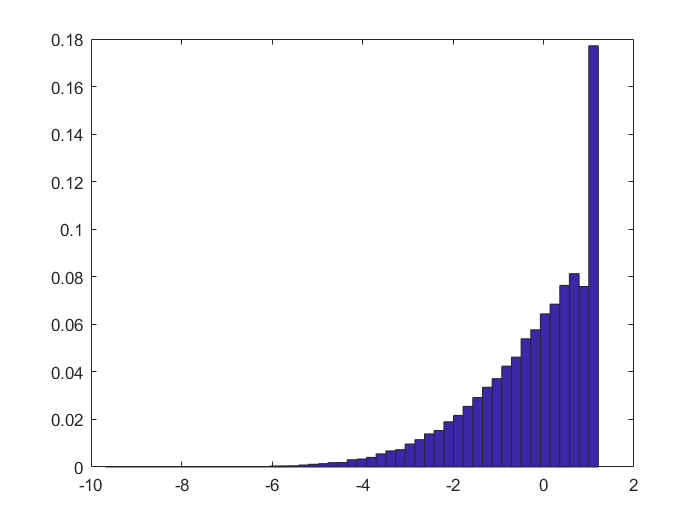

% data for drawing table
ns = [100,200,400,800];
cmean = zeros(4,1);
var = zeros(4,1);
cvar  = zeros(4,1);
cstd  = zeros(4,1);

tab = zeros(4,4);
for n = 1:4
    % different number of timesteps
    [cmean(n,1), var(n,1), cvar(n,1), cstd(n,1)] =  naivehedging(ns(n));
end

timesteps = {'100';'200';'400';'800'};


table(cmean, var, cvar, cstd, 'RowNames',timesteps)

ans = 4×4 table
            cmean        var       cvar       cstd 
           ________    _______    _______    ______

    100    -0.27694    -2.8394     -3.736    1.2884
    200    -0.27238     -2.834    -3.7134     1.281
    400    -0.28112    -2.8414    -3.7246     1.283
    800    -0.26743    -2.8205    -3.7141    1.2785


we observe the mean is always below zero.

mean,var, cvar, cstd are roughly constant with respect to number of timesteps.

(e)

in reality, time is continuous, but stock price is still discrete through time.

so even we buy stock as soon as stock price >= K, it may happens stock price > K.

similarly, we may sell stock at price < K.

So we tend to buy stock with higher price, and sell them at lower price, that's how we lose money.

In the theoritical model, we buy and sell stock at price == K. 

function [pandl, var, cvar, stdscore] = naivehedging(N)
    S0=95;
    K=105;
    M=80000;
    T=1;
    delta=zeros(M,1);
    S=ones(M,1).*S0;
    dt=T/N;
    r=0;
    mu =0.18 ;
    sigma = 0.23;
    C0=blsprice (S0,K,r,T,sigma);
    bond=ones(M,1).*C0; 
    
    % bond, delta, S are vector of length M we update each iteration
    for timestep = 1:N
        Snew = S.*exp((mu-0.5*sigma^2)*dt + sigma.* normrnd(0,1,M,1)*sqrt(dt));
        % if stock price change from <K to >=K, indicator = 1, we buy stock
        % if stock price change from >=K to <K, indicator= -1, we sell stock
        % otherwise, it is 0
        indicator = (Snew>=K)-(S>=K);
        % update bond and delta according to indicator
        delta = delta+indicator;
        bond = bond - indicator.*Snew;
        S=Snew;   
    end
    % calculate return values, draw histogram if there is 800 timesteps
    netvalue = (bond+S.*delta-max(0,S-K));
    pandl = netvalue./C0;
    [var,cvar] = dVaRCVaR(pandl, 0.05);
    stdscore = (std(pandl));
    if (N==800)
        drawPandL(pandl)
    end
    pandl = mean(pandl);

end
function drawPandL(pandl)
    % convinient function to draw histograms
    minv=(min(pandl));
    maxv=(max(pandl));
    range = minv: (maxv-minv)/50:maxv;
    counts = histc(pandl , range);
    bar(range, counts./length(pandl),'histc')
end

function [var,cvar] = dVaRCVaR(pandl, beta)
    n=length(pandl);
    pandl = sort(pandl);
    var = pandl(round(beta*n));
    cvar = mean(pandl(1:round(beta*n)));    
end


